Feature 1: ClearanceFactor

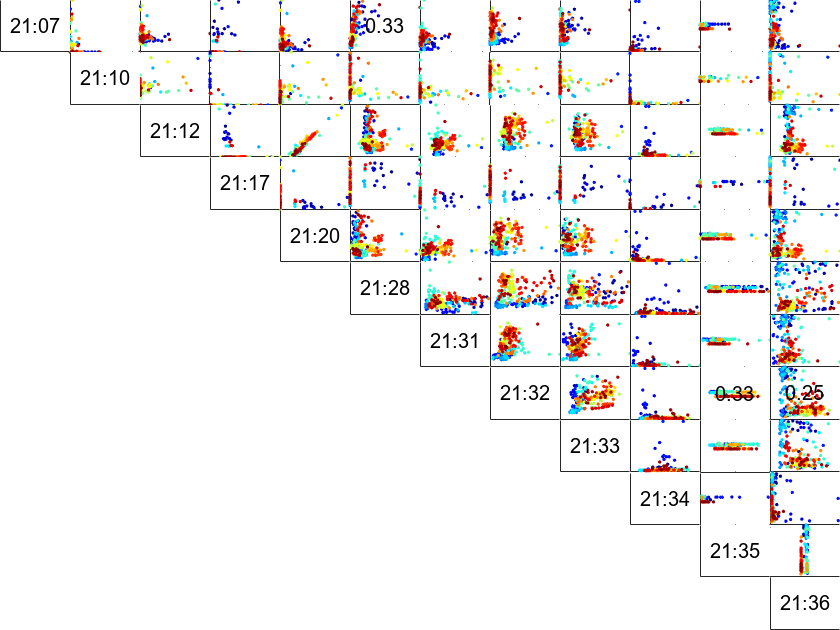

Feature 2: CrestFactor

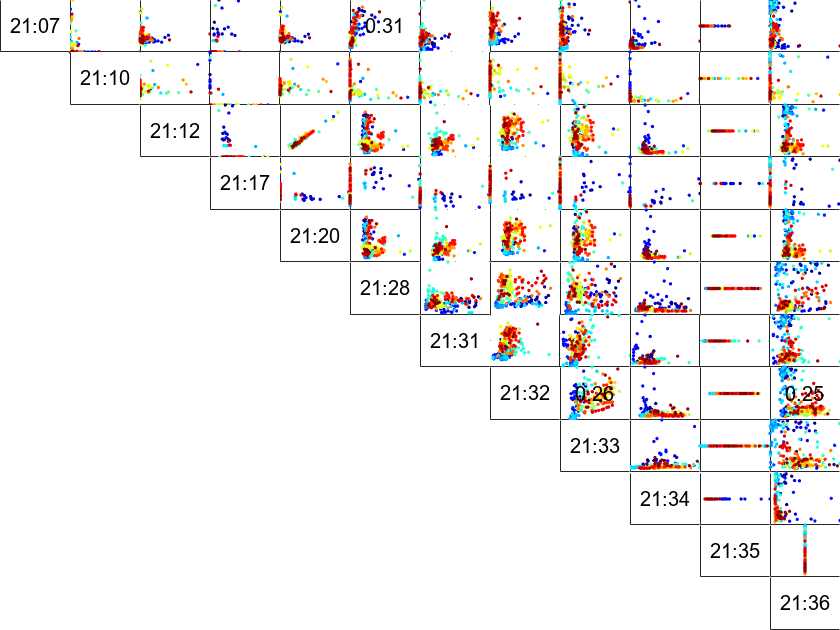

Feature 3: ImpulseFactor

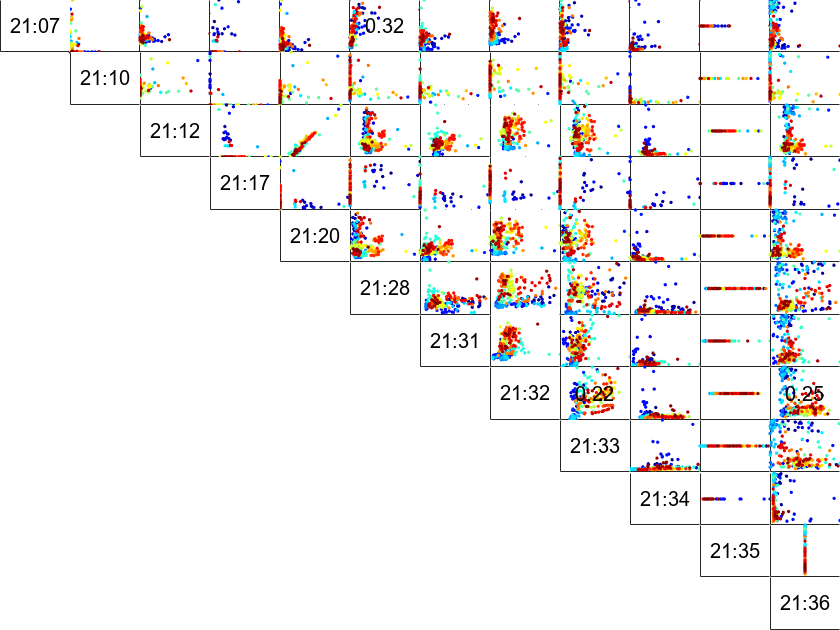

Feature 4: Kurtosis

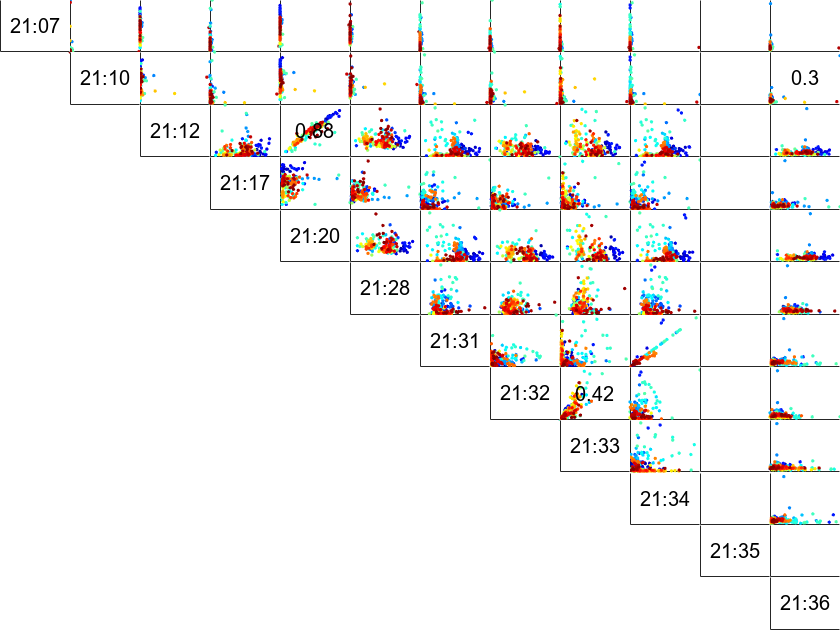

Feature 5: Mean

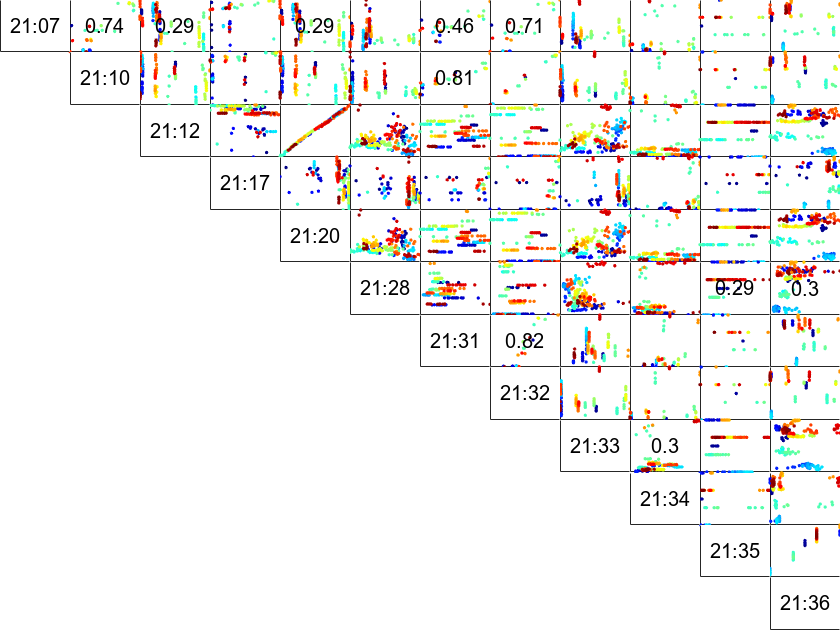

Feature 6: PeakValue

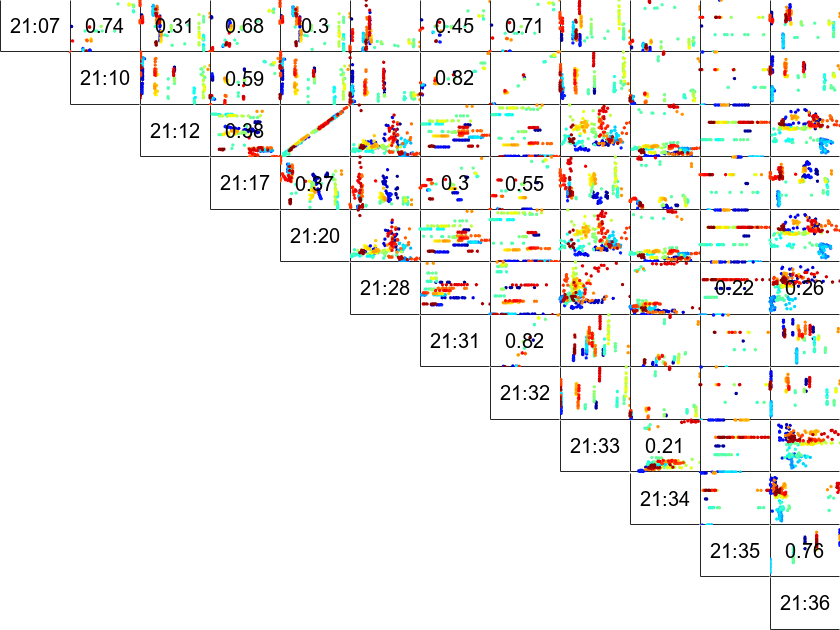

Feature 7: RMS

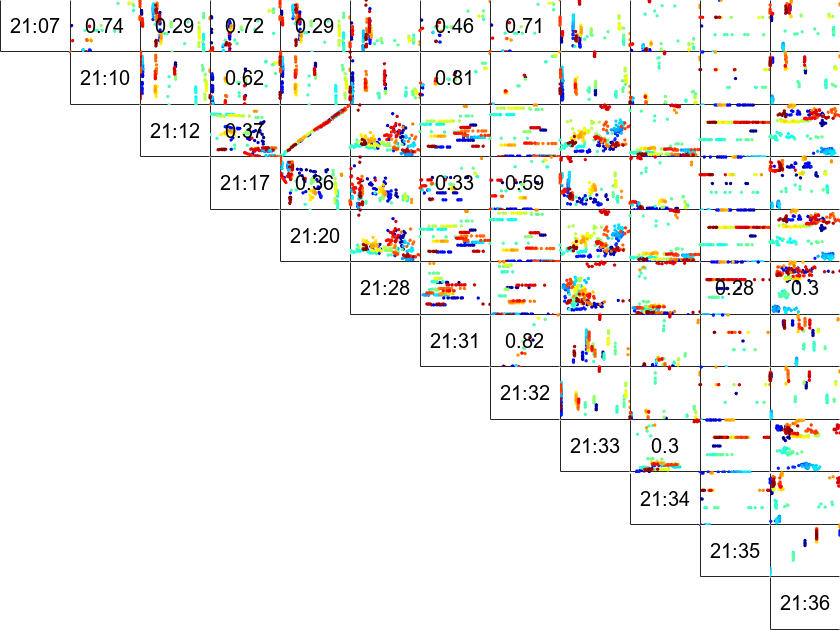

Feature 8: SNR

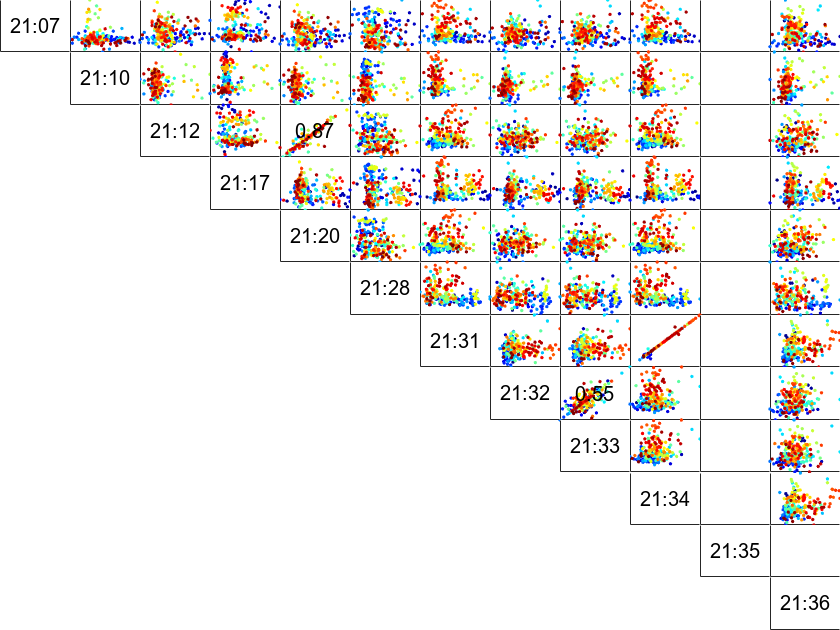

Feature 9: SINAD

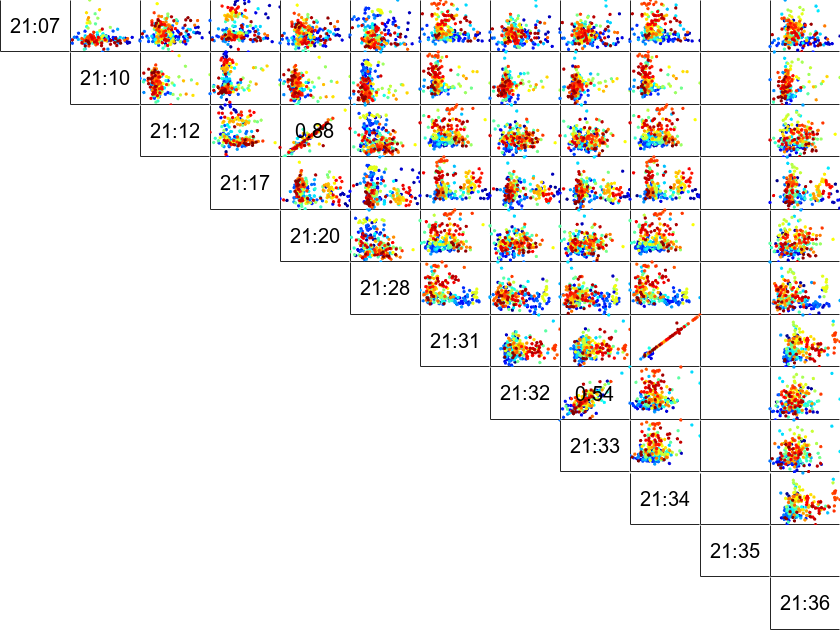

Feature 10: ShapeFactor

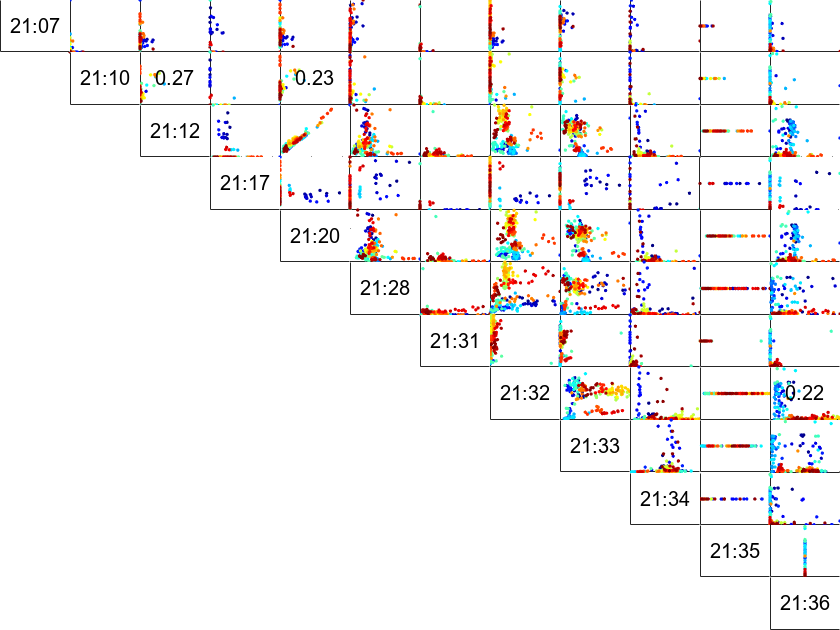

Feature 11: Skewness

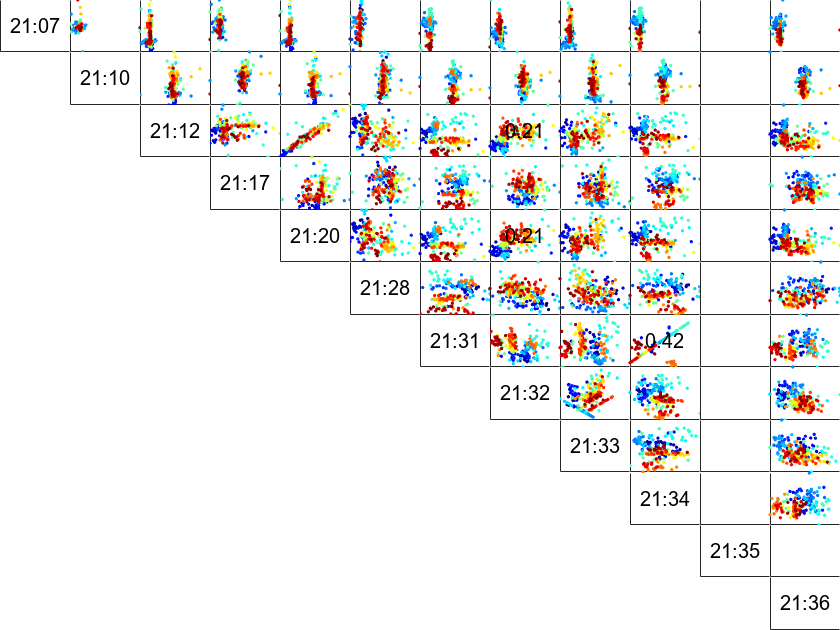

Feature 12: Std

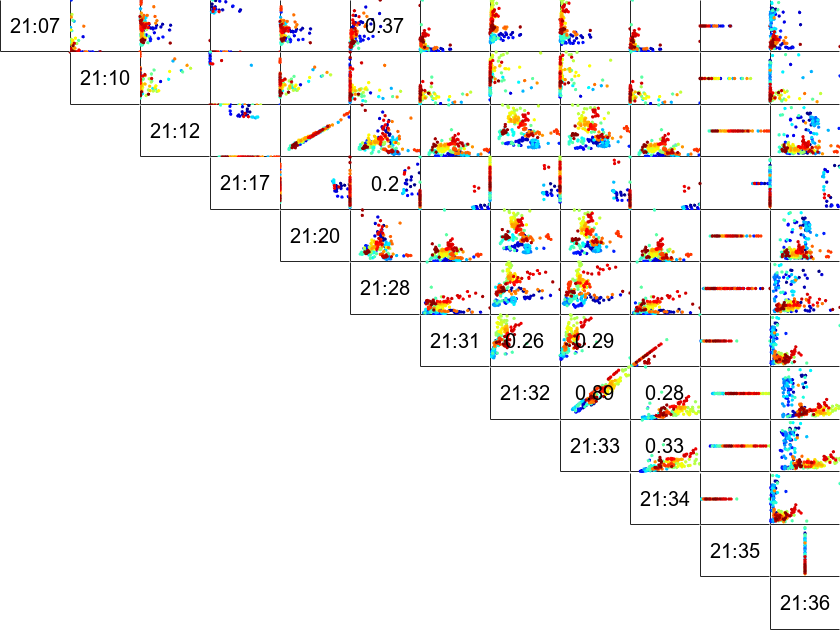

Feature 13: THD

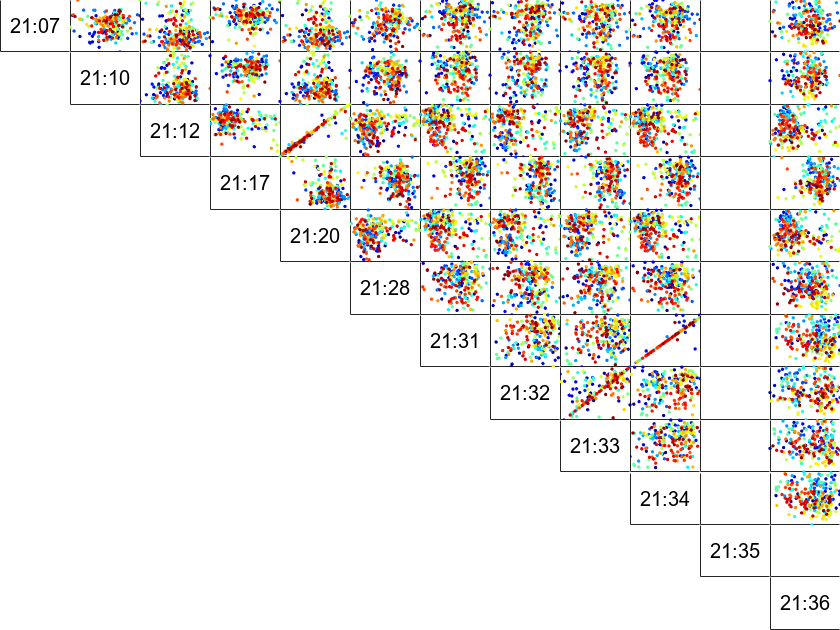

warning('off','all');
Features = DFD_FeatureTable_TimeDomain_Standard;
saveFigures = true;
for featureIndex = 1:numOfFeatures_Time
    fprintf("Feature %i: %s", featureIndex, FeatureNames_Combined(featureIndex));
    fnPlotSignalVsSignal(Features, 0.2, 0.9, featureIndex, featureNames_Time, signalNames_Time, sensorNames);        
    filename = "..\Latex Document\figures\SignalVsSignalFeatureTime" + featureIndex;
    if saveFigures 
        %export_fig(filename, '-eps', '-depsc');
        print(filename,'-depsc','-tiff');
    end
    
    %fnPlotSignalVsSignal(DFD_FeatureTable_TimeDomain_DcRemoved, 0.2, 0.9, featureIndex, FeatureNames, signalName, sensorNames);
    %fnPlotSignalVsSignal(DFD_FeatureTable_TimeDomain_Padded, 0.2, 0.9, featureIndex, FeatureNames, signalNames, sensorNames);
    %fnPlotSignalVsSignal(DFD_FeatureTable_TimeDomain_DcRemovedPadded, 0.2, 0.9, FeatureIndex, featureNames, signalNames, sensorNames);
end

featureIndex = 1

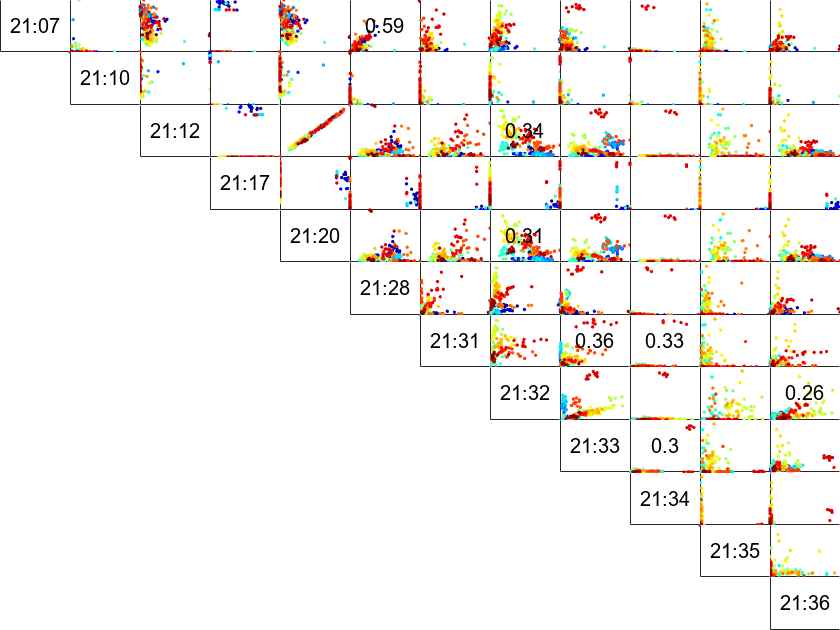

featureIndex = 2

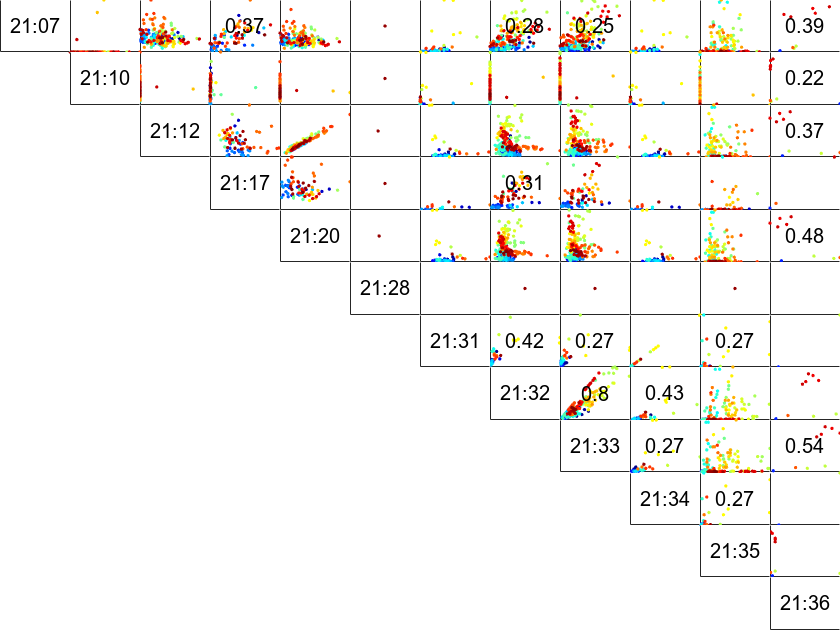

featureIndex = 3

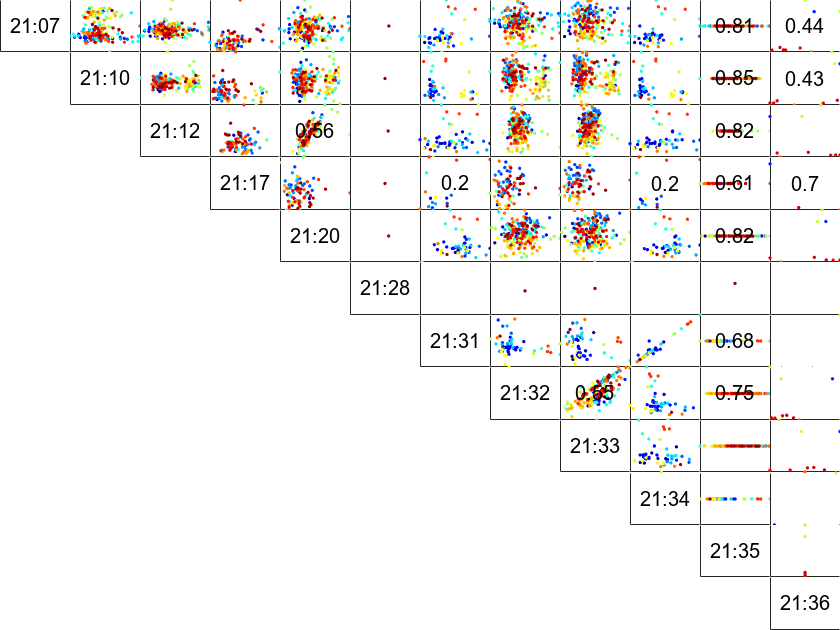

Features = DFD_FeatureTable_FreqDomain_Standard;
for featureIndex = 1:numOfFeatures_Freq
    featureIndex
    fnPlotSignalVsSignal(Features, 0.2, 0.9, featureIndex, featureNames_Freq, signalNames_Freq, sensorNames);        
    filename = "..\Latex Document\figures\SignalVsSignalFeatureFreq" + featureIndex;
    if saveFigures 
        %export_fig(filename, '-eps', '-depsc');
        print(filename,'-depsc','-tiff');
    end

    %fnPlotSignalVsSignal(DFD_FeatureTable_TimeDomain_DcRemoved, 0.2, 0.9, featureIndex, FeatureNames, signalName, sensorNames);
    %fnPlotSignalVsSignal(DFD_FeatureTable_TimeDomain_Padded, 0.2, 0.9, featureIndex, FeatureNames, signalNames, sensorNames);
    %fnPlotSignalVsSignal(DFD_FeatureTable_TimeDomain_DcRemovedPadded, 0.2, 0.9, FeatureIndex, featureNames, signalNames, sensorNames);
end